## **  PCS 130 Lab 5 Interference and Diffraction of Light**

In this lab we will be looking at the interference and diffraction of light. 

- Simulate the interference pattern and diffraction pattern of light through a single slit and double slit.

- Analyze the relationship between the slit width and slit separation on the diffraction and interference pattern of light.

- Determine the wavelength of a laser based on the diffraction pattern.

**Simulating the diffraction pattern using a single slit**

Often times before you perform an experiment you can simulate what might be expected based off of theory. In the below code block adjust the slit width, wavelength, screen size and distance to the screen based on your experimental set-up for a single slit trial. Generate a line plot of the intensity of the light on the screen as well as a visual simulation of the interference pattern.

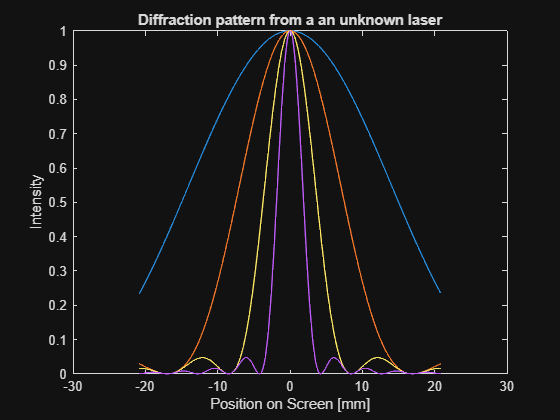

a = [2 4 8 16]*1e-5; %Slit width in m
l = 650e-9; % Estimated wavelength of your laser. Note that the colour of the laser is red. What range of wavelengths does the colour red fall under? 	
D = 1.042; % Distance to the screen in m
x = -.02:.0001:.02; %Screen Size - Range of values to plot against for the position on the screen, middle number denotes resolution

beta=pi*a'/l.*x;
intensity_single = (sin(beta+eps)./(beta+eps)).^2; %intensity of the light, eps is machine epsilon a small number added to beta for plotting purposes
x1 = x*D*1000; %actual position on the screen
plot(x1,intensity_single)
title('Diffraction pattern from a an unknown laser');
xlabel('Position on Screen [mm]')
ylabel('Intensity');

% %Diffraction pattern on screen
[x2, y2] = meshgrid(x1,[-1,1]);
z2 = [intensity_single.^0.25; intensity_single.^0.25]; %Here this value is raised to 0.25 to help scale and visualize the lower intensities
pcolor(x2, y2, z2)

Error using pcolor (line 21)
Matrix dimensions must agree.

shadingMap = gray(64);
colormap(shadingMap(:,1).*[0.8,0,0]);
shading interp

**Simulating the interference pattern using a double slit**

For the interference pattern using a double slit we can use a similar calculation for the diffraction pattern from the single slit, then factor in the interference. In the code block below, enter in the slit separation you are interested in. Uncomment the relevant lines of code in order for the script to run.

d_sep = [2.5 5 2.5 5]*1e-4 %slit separation input the slit separation value to simulate
alpha = (pi*d_sep'/D)/(l).*x;
intensity_double = intensity_single.*cos(alpha).^2 ;

% Line plot of the double slit intensity interference and diffraction
% pattern
plot(x1,intensity_double)
hold on
plot(x1,intensity_single,'--')
legend('Interference Pattern','Diffraction envelope')
title('Interference and Diffraction pattern from an unknown laser');
xlabel('Position on Screen [mm]')
ylabel('Intensity');
hold off

%Projected pattern on a sheet. Uncomment the lines below.
[x2, y2] = meshgrid(x1,[-1,1]);
z3 = [intensity_double.^0.25; intensity_double.^0.25]; %Here the intensities are scaled by 0.25 in order for them to be more visually prominent on the plot.
pcolor(x2, y2, z3)
shadingMap = gray(64);
colormap(shadingMap(:,1).*[0.8,0,0]);
shading interp

**Analysing the relationship between slit width and distance of diffraction maxima**

Based on the recorded markings in the single slit scenario record your trials in the code block below. Generate a linear plot comparing the slit width versus the distance from the central maxima to the first and second order minima. Remember that your plot must represent the equation for the single slit scenario be sure to plot your axes with the correct variable.

Once you generate your plots and linear fit. Extract the wavelength of the light based on the slope. Is there a difference between the first order slope and second order slope? Remember to include any error or uncertainty when reporting your final values.

a_data = [2 4 8 16]*1e-5 %slit widths
y1_single = [31.05 15.05 8.175 4.5]*1e-3 % distances from first order minima to central maxima
y2_single = [61.7 30.55 19 8.75]*1e-3 % distances from second order minima to central maxima
single_slit_model1 = fitlm(1./a_data, y1_single) %Insert variables needed to generate a linear plot with the slope.
single_slit_model2 = fitlm(1./a_data, y2_single) %Insert variables needed to generate a linear plot with the slope.
plot(single_slit_model1) % Generate plot needed to extract the slope.
hold on
plot(single_slit_model2)
title('Single Slit Linear Fit y vs (1/a)');
xlabel('1/a [1/m]')
hold off
% get wave length from slope
% For single slit minima: a * sin(theta) = m * lambda -> for small angles sin(theta) ~ y/D
% So y = (m*lambda/D) * a  -> slope = m*lambda/D. Use first-order (m=1) slopes from fits.
slope1 = single_slit_model1.Coefficients.Estimate(2); % slope for y1 vs a
slope2 = single_slit_model2.Coefficients.Estimate(2); % slope for y2 vs a (m=2)
lambda_from_y1 = slope1 * D; % m=1
lambda_from_y2 = (slope2 * D) / 2; % divide by m=2 to get lambda
fprintf('Estimated wavelength from first-order single-slit slope: %.3e m\n', lambda_from_y1);
fprintf('Estimated wavelength from second-order single-slit slope: %.3e m\n', lambda_from_y2);


**Analysing the relationship between slit separation and distance of interference maxima**

Based on the recorded markings in the double slit scenario record your trials in the code block below. Generate a linear plot comparing the slit separation for a constant width versus the distance from the central maxima to the first and second order maximas. Using your recorded value for the variable double slit and your model, determine the unknown slit separation.

d_data = 1./[2.5 5 2.5 5]*1e-4; % slit separations in meters (positive values)
y1_double = [1.3 1.02 1.8 0.7]*1e-3; % first-order maxima distances (m), corrected signs/units
y2_double = [2.6 2.04 3.6 1.4]*1e-3; % second-order maxima distances (m), corrected (approx. doubled from y1)
double_slit_model1 = fitlm(d_data, y1_double) %Insert variables needed to generate a linear plot with the slope.

double_slit_model1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat     pValue 
                   ________    __________    _______    _______

    (Intercept)    0.00017     0.00046931    0.36224    0.75187
    x1                34.5         14.841     2.3247    0.14567


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.000297
R-squared: 0.73,  Adjusted R-Squared: 0.595
F-statistic vs. constant model: 5.4, p-value = 0.146

double_slit_model2 = fitlm(d_data, y2_double) %Insert variables needed to generate a linear plot with the slope.

double_slit_model2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat     pValue 
                   ________    __________    _______    _______

    (Intercept)    0.00034     0.00093862    0.36224    0.75187
    x1                  69         29.682     2.3247    0.14567


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.000594
R-squared: 0.73,  Adjusted R-Squared: 0.595
F-statistic vs. constant model: 5.4, p-value = 0.146

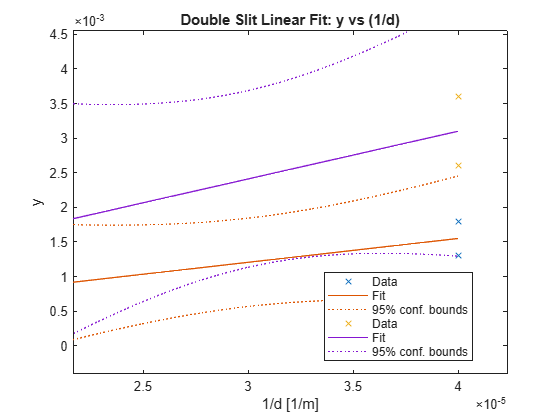

plot(double_slit_model1) % Generate plot needed to extract the slope.
hold on
plot(double_slit_model2)
title('Double Slit Linear Fit: y vs (1/d)')
xlabel('1/d [1/m]')
hold off


% For double slit maxima: d * sin(theta) = m * lambda -> y = (m*lambda/D) * d
% Use first-order fits if available. d_data given in 1e4 units earlier; ensure units consistent.
slope_d1 = double_slit_model1.Coefficients.Estimate(2);
slope_d2 = double_slit_model2.Coefficients.Estimate(2);
lambda_from_d1 = slope_d1 * D; % m=1
lambda_from_d2 = (slope_d2 * D) / 2; % m=2
fprintf('Estimated wavelength from first-order double-slit slope: %.3e m\n', lambda_from_d1);

Estimated wavelength from first-order double-slit slope: 3.595e+01 m


fprintf('Estimated wavelength from second-order double-slit slope: %.3e m\n', lambda_from_d2);

Estimated wavelength from second-order double-slit slope: 3.595e+01 m
